# lora sim script

## lora parameters

clear;
SF=7; %spreading factor 7-12
Fs=125e3;%samplingrate = BW
SPS=2^SF;%samples per symbol



## sim parameters

%data
numSym=84;
randomData=true;
%channel
maxDopplerShift=0;
maxSNR=25; %signal to noise ratio in dB
%loops
nLoops=1;
loopSNR=false;
loopDoppler=false;

## tx

%generate data
dataLength=numSym*SF;% SF bits per symbol
if randomData
    messageBits= randi([0 1],dataLength,1);
else
    messageBits=ones(dataLength,1);
end
%generate lora signal
loraSignal=generateLoraSignal(messageBits,SF,numSym);

decimalSymbols =    126   115    86    81    79    31    86   105   121   125     0    80    20   101   108   104    85    61    12   104   100    34   116    66    24   119   100    98    81    16   105   124    23    50    14     3    80    36    20    92    97    41    75   104   123    11    77   100   117    82


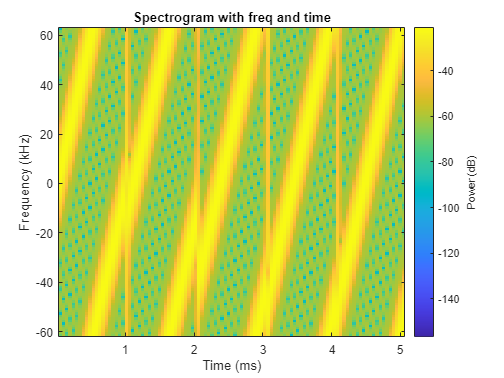

%spectroram of first 5 symbols
figure
windowLength=round((SPS)/10);
spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
title('Spectrogram with freq and time')

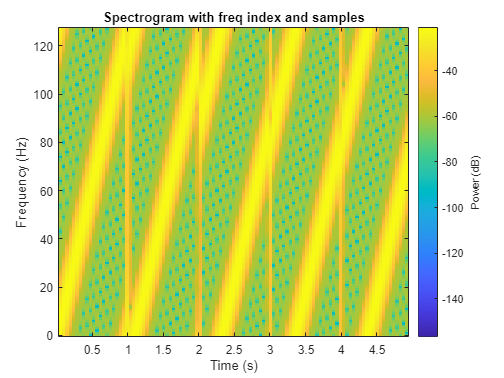

figure
spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
title('Spectrogram with freq index and samples')

## channel

## rx

## ber